# Analysis

La funzione errorVsSNR_M disegna un grafico che rappresenta la probabilità di errore, sia sperimentale che teorica, in funzione del rapporto energia su rumore e del numero di simboli nella modulazione. Il suo primo parametro è la modulazione digitale che si vuole utilizzare: si noti che di tale oggetto non importano le proprietà (M e averageEnergy), bensì *solo* il tipo della modulazione. Questo è perché sono i seguenti due parametri di errorVsSNR_M a specificare sia i rapporti energia su rumore che i numeri di simboli. L'ultimo parametro invece specifica il numero di prove Monte Carlo per ciascuna combinazione SNR - M.

Le 4 modulazioni di sotto riportate potevano essere inizializzate con qualunque parametro iniziale, non faceva differenza nei grafici. Per ciascun grafico vengono simulate 30 combinazioni: 10 possibili SNR (suddivise tra -10 e 5 dB) per 3 possibili numeri di segnali (4, 16 e 64). Si effettuano 50 000 prove per ciascuna combinazione. Vengono rappresentati 60 punti in totale, poiché oltre ai rapporti di errore simulati sono anche disegnate le probabilità di errore teoriche: upper bound per PSK e PPM, esatte per PAM e QAM (come si vede dai grafici).

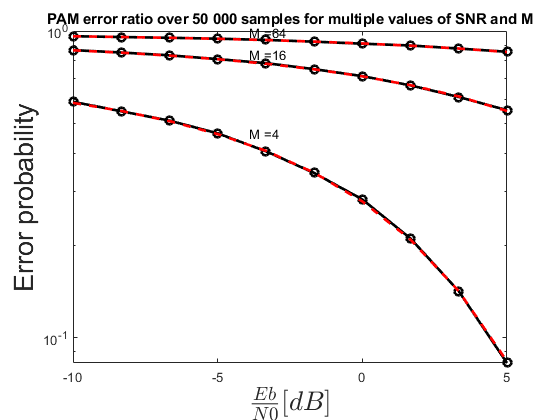

pam = PAM(10, 10); % Parametri irrilevanti per i grafici errorVsSNR_M
qam = QAM(10, 10);
psk = PSK(10, 10);
ppm = PPM(10, 10);

errorVsSNR_M(pam, linspace(-10,5,10),[4 16 64], 50000);
title('PAM error ratio over 50 000 samples for multiple values of SNR and M');

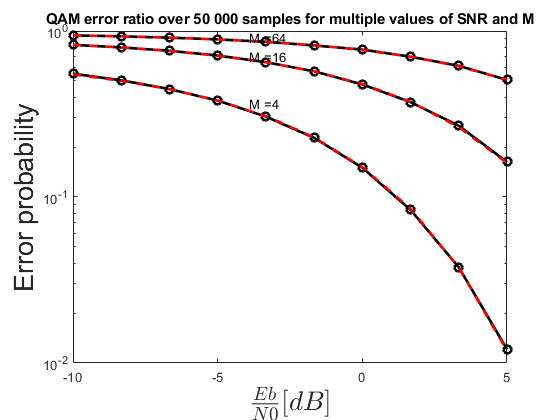

errorVsSNR_M(qam, linspace(-10,5,10),[4 16 64], 50000);
title('QAM error ratio over 50 000 samples for multiple values of SNR and M');

I seguenti grafici rappresentano in rosso non le probabilità di errore esatte, bensì l'upper bound. Si nota che è più vicino alla probabilità d'errore esatta per valori più alti di SNR.

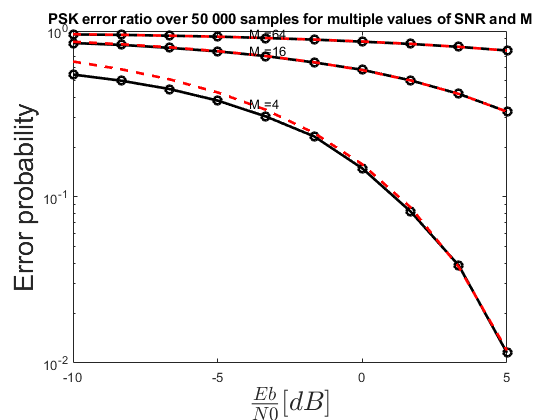

errorVsSNR_M(psk, linspace(-10,5,10),[4 16 64], 50000);
title('PSK error ratio over 50 000 samples for multiple values of SNR and M');

Il seguente grafico della PPM evidenzia chiaramente il limite di Shannon.

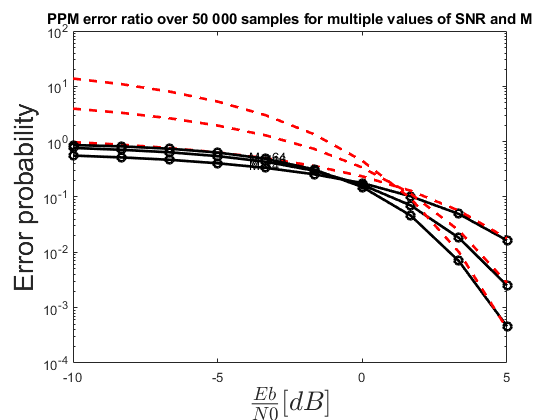

errorVsSNR_M(ppm, linspace(-10,5,10),[4 16 64], 50000);
title('PPM error ratio over 50 000 samples for multiple values of SNR and M');